# EECS 965 Homework 07                                 William Powers 2025

#### ***1. Determine the likelihood functions ***$Pr(x|H_0)$ and $Pr(x|H_1)$*. In other words, determine the numerical values of the 12 probabilities (*$p_{00}, p_{10}, ...$* and *$p_{01}, p_{11}, ...$*) in the lists above.*

The discrete likelihood functions for the biased and unbiased coin are computed using a binomial distribution 


$$Pr(x|H_i) = \binom{5}{x}P(\text{'heads'}|H_i)^x(1-P(\text{'heads'}|H_i))^{5-x}$$


therefore the exhaustive list of probabilities for each hypothesis is


$$Pr(x=0|H_0) = 0.0312$$
    
$$Pr(x=0|H_1) = 0.00097$$



$$Pr(x=1|H_0) = 0.1562$$
    
$$Pr(x=1|H_1) = 0.0146$$



$$Pr(x=2|H_0) = 0.3125$$
    
$$Pr(x=2|H_1) = 0.0878$$



$$Pr(x=3|H_0) = 0.3125$$
    
$$Pr(x=3|H_1) = 0.2636$$



$$Pr(x=4|H_0) = 0.1562$$
    
$$Pr(x=4|H_1) = 0.3955$$



$$Pr(x=5|H_0) = 0.0312$$
    
$$Pr(x=5|H_1) = 0.2373$$


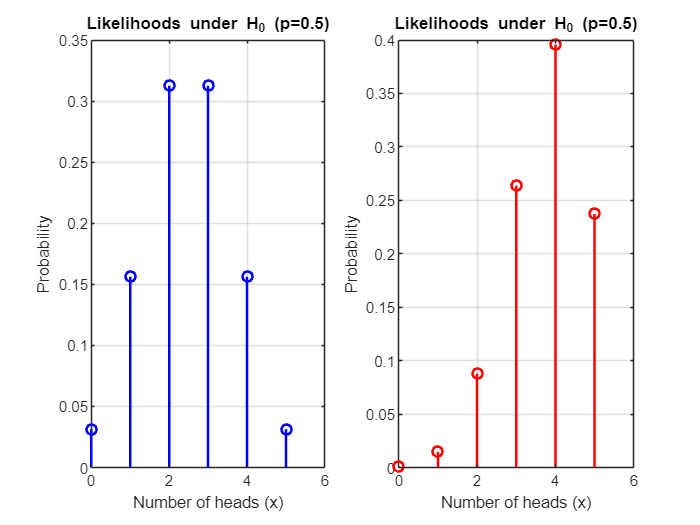

% number of flips
n = 5;
x = 0:n;

% hypothesis 0 distribution
p0 = binopdf(x, n, 0.5);

% hypothesis 1 distribution
p1 = binopdf(x, n, 0.75);

figure("Name", "Discrete Likelihood Functions");
subplot(1, 2, 1);
stem(x, p0, 'b', 'LineWidth', 1.5);
xlabel('Number of heads (x)');
ylabel('Probability');
title('Likelihoods under H_0 (p=0.5)');
grid on;
subplot(1, 2, 2);
stem(x, p1, 'r', 'LineWidth', 1.5);
xlabel('Number of heads (x)');
ylabel('Probability');
title('Likelihoods under H_0 (p=0.5)');
grid on;

#### *2. Say the decision rule is*

#### Choose  $H_0$  if  $x < y\prime$

#### Choose  $H_1$  if  $x \ge y\prime$

#### *where*

#### $y\prime \in \{0, 1, 2, 3, 4, 5, 6 \}$*.*

#### *Sketch the ROC for this detection problem. This ROC should consist of 7 points on the *$(P_{FA}, P_D)$* plane. Provide the specific coordinates of each of these seven points.*

To construct the receiver operator curve, the intergal definitions for $P_D$ and $P_{FA}$ must first be defined over the interval $\mathcal{R}_1 = \{y\prime, \infty\}$


$$P_{FA} = P(T_d(x) = x\in \mathcal{R}_1|H_0) = \int_{x \in \mathcal{R}_1} p(x|H_0)dx$$



$$P_{D} = P(T_d(x) = x\in \mathcal{R}_1|H_1) = \int_{x \in \mathcal{R}_1} p(x|H_1)dx$$


Becuase the likelihood functions are discrete, these intergals are rewritten as summations where $y\prime \in \{0, 1, 2, 3, 4, 5, 6 \}$


$$P_{FA} =  \sum_{x=y\prime}^{5} Pr(x|H_0)dx$$



$$P_{D} =  \sum_{x=y\prime}^{5} Pr(x|H_1)dx$$


and then plotted using the probabilities found in (a).

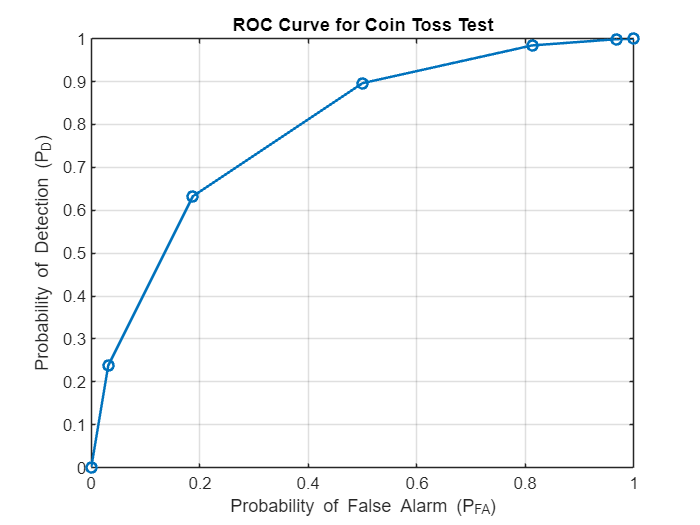

n = 5;
x = 0:n;
P_FA = zeros(n+2,1);
P_D  = zeros(n+2,1);

for i = 0:n
    P_FA(i+1) = sum(binopdf(i:n, n, 0.5));
    P_D(i+1) = sum(binopdf(i:n, n, 0.75));
end
% Plot ROC curve
figure("Name","ROC");
plot(P_FA, P_D, '-o', 'LineWidth', 1.5, 'MarkerSize', 6);
xlabel('Probability of False Alarm (P_{FA})');
ylabel('Probability of Detection (P_D)');
title('ROC Curve for Coin Toss Test');
grid on;
axis([0 1 0 1]);

#### *3. Say the a priori probability of a biased coin is *$Pr(H_1) = 1/3$*. Use the MAP detection criterion to form a decision rule of the form*

#### Choose  $H_0$  if  $x < y\prime$

#### Choose  $H_1$  if  $x \ge y\prime$

#### *where *$y\prime$* is an interger.*

Given the a prioris of seeing a biased and unbiased coin as $Pr(H_1) = 1/3$ and $Pr(H_0)=2/3$ respectively, the maximum a posteriori probabilities can be determined.


$$Pr(H_0|x) = \frac{Pr(x|H_0)Pr(H_0)}{Pr(x|H_0)Pr(H__0) + Pr(x|H_1)Pr(H_1)}$$
        
$$Pr(H_1|x) = \frac{Pr(x|H_1)Pr(H_1)}{Pr(x|H_0)Pr(H__0) + Pr(x|H_1)Pr(H_1)}$$


Plugging in the discrete likelihood functions and a prioris, the above is expressed and simplified as


$$Pr(H_0|x) =

\frac{\left(\binom{5}{x}(0.5)^x(1-0.5)^{5-x} \right)(2/3)}{\left(\binom{5}{x}(0.5)^x(1-0.5)^{5-x} \right)(2/3) + \left(\binom{5}{x}(0.75)^x(1-0.75)^{5-x} \right)(1/3)} = 

\frac{64}{64+ 3^x}$$



$$Pr(H_1|x) =

 \frac{\left(\binom{6}{x}(0.75)^x(1-0.75)^{6-x} \right)(1/3)}{\left(\binom{6}{x}(0.5)^x(1-0.5)^{6-x} \right)(2/3) + \left(\binom{6}{x}(0.75)^x(1-0.75)^{6-x} \right)(1/3)} = 

\frac{3^x}{64+ 3^x}$$


Using these two a posteriori probabilities, a likelihood ratio test (LRT) is formed

Choose  $H_0$  if  $\frac{Pr(H_1|x)}{Pr(H_0|x)} =L(x) \lt 1.0$      Choose  $H_1$  if  $\frac{Pr(H_1|x)}{Pr(H_0|x)} =L(x) \ge 1.0$

where


$$L(x) = \frac{\frac{3^x}{64+ 3^x}}{\frac{64}{64+ 3^x}} = \frac{3^x}{64}$$


Plugging this into the LRT and further simplifying gives

Choose  $H_0$  if  $x \lt \frac{\ln(64)}{\ln(3)} \approx 3.78$      Choose  $H_1$  if  $x \ge \frac{\ln(64)}{\ln(3)} \approx 3.78$

#### *4. Determine the probability of error *$Pr(e)$* of this MAP decision rule.*

The probability of error is found is the probabilistic view of making the wrong decision. Mathmatically, this is found as the expected value of the conditional distribution between the error $e$ and measurement $x$.


$$Pr(e) = \sum Pr(e|x)Pr(x)$$


For the MAP decision rule derived in (3),


$$Pr(e|x) =
\begin{cases}
1 - Pr(H_0|x) & \text{for } x \in \{ 0, ..., 3 \}] \\ 
1 - Pr(H_1|x) & \text{for }  x \in \{4, ..., 5 \}]
\end{cases}$$
    
$$\rightarrow$$
    
$$Pr(e|x) =
\begin{cases}
1 - \frac{64}{64+ 3^x} & \text{for } x \in \{ 0, ..., 3 \}] \\ 
1 - \frac{3^x}{64+ 3^x} & \text{for }  x \in \{4, ..., 5 \}]
\end{cases}$$



$$Pr(x) = \left(\binom{5}{x}(0.5)^x(1-0.5)^{5-x} \right)(2/3) + \left(\binom{5}{x}(0.75)^x(1-0.75)^{5-x} \right)(1/3)$$


Plugging this into the equation for $Pr(e)$ yeilds


$$Pr(e) = 
\sum_{x=0}^3 \left( 1 - \frac{64}{64+ 3^x} \right)Pr(x) + 

 \sum_{x=4}^5 \left( 1 - \frac{3^x}{64+ 3^x} \right) Pr(x)$$



$$Pr(e) = 0.247$$
